%Just a toy need 
Need = 10000;

% Reads capacity of each type of plant
Cap = xlsread('EnergySources.xlsx', 'l2:l21');
Seeds = xlsread('Random_seeds.xlsx', 'a1:a20');
% the lower bound for each type of plant is 0
lb =  zeros(1,20);
% the upper bound for each type of plant is the need divided by the capacity for each plant
ub = Need./Cap;

% using the options from "solving a mixed-integer engineering design problem using the genetic algorithm" matlab sample problem
opts = optimoptions(@gamultiobj, ...
                    'CreationFcn',@Individuals, ...
                    'PopulationSize', 150, ...
                    'MaxGenerations', 200, ...
                    'FunctionTolerance', 1e-16, ...
                    'MutationFcn', @int_mutation,...
                    'CrossoverFcn',@int_crossoverarithmetic,...
                    'PlotFcn', @gaplotpareto);

%objective function is defined with name KnapsackWeight, have also defined a function called knapsack constraints.
% 20 refers to the number of variables. Since I have 20 different technologies defined, there are 22
%corresponding to a number of copies of each technology.

The multiobjective GA function in MATLAB does not allow you to specify integer constraints. This can be overcome by manually creating the population function and crossover and mutation functions. Samples are provided in exampleIntGAMULTIOBJ.m. For now I am using their crossover and  mutation functions. 

Each iteration uses a different random seed. Pareto sets for each seed are stored in an excel file. They are also combined into one array, and the unique values of the array are stored into a solutions file. 

Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


Optimization terminated: maximum number of generations exceeded.


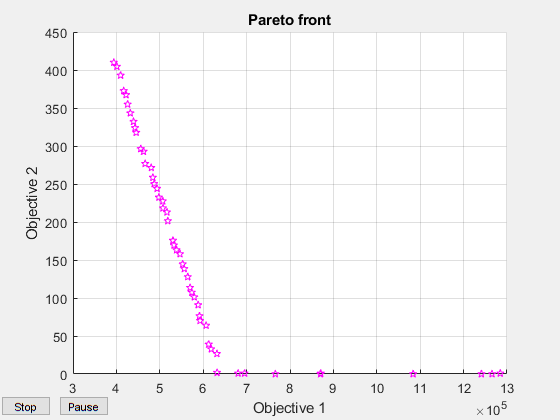

Optimization terminated: maximum number of generations exceeded.


All_runs = [];
for k = 1:20
    
%random number generator seed is from Seeds and uses Mersenne Twister (this is default)                
    rng(Seeds(k), 'twister');

    [xbest, fbest, exitflag] = gamultiobj(@KnapsackWeightMulti, 20, [], [], [], [], ...
        lb, ub, @const_knap_70VRE, opts);
    % take just the unique solns in the Pareto set
    Pareto_solns = unique(xbest,'rows');
    % then append the unique solns to the others from previous runs
    All_runs  = [All_runs; Pareto_solns];
    filename = sprintf('Const_70VRE_Pareto_%d',k);
    xlswrite(filename,Pareto_solns);
end


Solutions = unique(All_runs, 'rows');
xlswrite('Const_70VRE_solutions.xlsx',Solutions);    
    